clc; clear; clf, close all;

for z = {'Facil', 'Intermedio'}
% ------------------------------------------ Main for loop ------------------------------------------
    disp(z) 

typeI = char(z);
Folders.FolderCodes = 'D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Codes\';
Folders.FolderCodesTests = 'D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Codes\Tests\';
Folders.FolderCodesFunc = 'D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Codes\Functions\';
Folders.FolderNGI = ['D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Imagenes_ionogramas\', typeI, '\NGI\'];
Folders.FolderGT = ['D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Imagenes_ionogramas\', typeI, '\IonogramImagesGT\'];


% Random file
fileList = dir(fullfile(Folders.FolderNGI, '/*.ngi'));
% randomIdx = randi(length(fileList), 1, 1);
% zippedDataFrame = fileList(randomIdx).name;

clear i
for i = 1:length(fileList)
    zippedDataFrame = fileList(i).name;

    % zippedDataFrame = 'varJM91J_2021249000303.ngi';% 'varJM91J_2021249181804.ngi';
    
    % Get data
    cd(Folders.FolderCodesFunc)
    IonogramData = GettingRelevantData(zippedDataFrame, Folders);
    
    % CustomPlot(IonogramData, IonogramData.totalpowerData)
    
    % Test Glob Thresh
    cd(Folders.FolderCodesTests)
    % TestingThresh
    [OMode, XMode, TPower]  = testingvar_(IonogramData, Folders, zippedDataFrame);
    
    % figure, imagesc(flip(TPower.imgDen)), colorbar
    % figure, imagesc(flip(TPower.imgLaplacian)), colorbar
    % figure, imagesc(flip(TPower.imgOutliners)), colorbar
    % figure, imagesc(flip(TPower.imgThresh)), colorbar
    
    % Precision = TPower.TP/(TPower.TP+TPower.FP)
    % Recall = TPower.TP/(TPower.TP+TPower.FN)

    cd(Folders.FolderCodesFunc)
    clear T_1 Precision_T1 Recall_T1 varFolder TP FP FN TN
    
    T_1 = 0:round(max(TPower.imgDen(:)))+1;
    for i = T_1
        % Thresholding global test 1 -- Intensity value reduction
            imgThresh_T1 = ThreshImg_Global(TPower.imgDen, i);
            [TP_TestTh1, FP_TestTh1, FN_TestTh1, TN_TestTh1] = IoUsimple(imgThresh_T1, TPower.iGT);
            
            TP(i+1) = TP_TestTh1; FP(i+1) = FP_TestTh1; FN(i+1) = FN_TestTh1; TN(i+1) = TN_TestTh1;
            
            Precision_T1(i+1) = TP_TestTh1/(TP_TestTh1 + FP_TestTh1);
            Recall_T1(i+1) = TP_TestTh1/(TP_TestTh1 + FN_TestTh1);  
    end
    T_1 = T_1';  Precision_T1 =  Precision_T1'; Recall_T1 = Recall_T1'; TP = TP'; FP = FP'; FN = FN'; TN = TN';
    varNames = {'Threshold', 'Precision', 'Recall', 'TP', 'FP', 'FN', 'TN'};
    Test_1 = table(T_1, Precision_T1, Recall_T1, TP, FP, FN, TN, 'VariableNames',varNames);
    
    % Best thresh
    Best_Thresh_1_idx = find(Precision_T1 == max(Precision_T1);
    Best_Thresh_Test1_Precision = T_1(double(Best_Thresh_1_idx));
    Best_Test1_Precision = Precision_T1(double(Best_Thresh_1_idx));
    
    
    clear T_2 Precision_T2 Recall_T2 TP FP FN TN i 
    T_2 = unique(round(TPower.imgOutliners(:), 2));
    for i = 1:length(T_2)
        
        % Thresholding global test 2 -- Outliners
            imgThresh_T2 = ThreshImg_Global(TPower.imgOutliners, T_2(i));
            [TP_TestTh2, FP_TestTh2, FN_TestTh2, TN_TestTh2] = IoUsimple(imgThresh_T2, TPower.iGT);
            
            TP(i) = TP_TestTh2; FP(i) = FP_TestTh2; FN(i) = FN_TestTh2; TN(i) = TN_TestTh2;
            
            Precision_T2(i) = TP_TestTh2/(TP_TestTh2 + FP_TestTh2);
            Recall_T2(i) = TP_TestTh2/(TP_TestTh2 + FN_TestTh2);
    end
    Precision_T2 =  Precision_T2'; Recall_T2 = Recall_T2'; TP = TP'; FP = FP'; FN = FN'; TN = TN';
    varNames = {'Threshold', 'Precision', 'Recall', 'TP', 'FP', 'FN', 'TN'};
    Test_2 = table(T_2, Precision_T2, Recall_T2, TP, FP, FN, TN, 'VariableNames',varNames);
    
    % Best thresh
    Best_Thresh_2_idx = find(unique(Precision_T2) == max(Precision_T2));
    Best_Thresh_Test2_Precision = T_2(double(Best_Thresh_2_idx));
    Best_Test2_Precision = Precision_T2(double(Best_Thresh_2_idx));
    
    clear T_1 Precision_T1 Recall_T1 T_2 Precision_T2 Recall_T2 TP FP FN TN imgThresh_T1 TP_TestTh1 FP_TestTh1 ...
        FN_TestTh1 TN_TestTh1 imgThresh_T2 TP_TestTh2 FP_TestTh2 FN_TestTh2 TN_TestTh2 i varNames
    
    %varmat = [zippedDataFrame, 'Test_1_'];
    
    varNames = {'Ionogram name', 'Best Thresh - T1', 'Best Thresh - T2'};
    varzipdata = strrep(zippedDataFrame,'.ngi','');
    Best_Thresh = table(string(varzipdata), Best_Thresh_Test1_Precision, Best_Thresh_Test2_Precision, 'VariableNames',varNames);
    
    
    varFolder = ['D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Imagenes_ionogramas\', typeI, '\Metrics_Tests\'];
    
    cd(varFolder)
    
    save([varzipdata, '_Test_Thresholds.mat'], 'Test_1', 'Test_2')
    save([varzipdata, '_Best_Thresh.mat'], 'Best_Thresh')
    
    clear varzipdata varFolder varNames Best_Thresh_Test1_Precision Best_Thresh_Test2_Precision
    %cd(Folders.FolderCodesFunc)

    % Test laplacian thresh
end

clear i Test_1 Test_2 Best_Thresh Best_Thresh_2_idx varzipdata a_ Best_Thresh_1_idx 

for i = 1:length(fileList)
    a_ = fileList(i).name;
    varzipdata = strrep(a_,'.ngi','');
    load([varzipdata, '_Best_Thresh.mat'])
    
    b_(i) = Best_Thresh.("Ionogram name");
    c_(i) = Best_Thresh.("Best Thresh - T1");
    d_(i) = Best_Thresh.("Best Thresh - T2");
    
end
b_ = b_'; c_ = c_'; d_ = d_';

varNames = {'Ionogram name', 'Best Thresh - T1', 'Best Thresh - T2'};
ThreshPlot = table(b_, c_, d_, 'VariableNames', varNames);

clear i varzipdata varNames Best_Thresh a_ b_ c_ d_

if z == "Facil"
    Thresh_Facil.Best_T1 = ThreshPlot.("Best Thresh - T1");
    Thresh_Facil.Best_T2 = ThreshPlot.("Best Thresh - T2");
    Thresh_Facil.Best_T1_Precision = Best_Test1_Precision;
    Thresh_Facil.Best_T2_Precision = Best_Test2_Precision;
end

if z == "Intermedio"
    Thresh_Intermedio.Best_T1 = ThreshPlot.("Best Thresh - T1");
    Thresh_Intermedio.Best_T2 = ThreshPlot.("Best Thresh - T2");
    Thresh_Intermedio.Best_T1_Precision = Best_Test1_Precision;
    Thresh_Intermedio.Best_T2_Precision = Best_Test2_Precision;
end


% histogram(ThreshPlot.("Best Thresh - T1"))
% boxplot(ThreshPlot.("Best Thresh - T1"))
% title([z, " Histogram - Best T1"])

% histogram(ThreshPlot.("Best Thresh - T2"))
% boxplot(ThreshPlot.("Best Thresh - T2"))
% title([z, " Histogram - Best T2"])

clear ThreshPlot Best_Test1_Precision Best_Test2_Precision
% ------------------------------------------ Main for loop ------------------------------------------

end

    {'Facil'}

    {'Intermedio'}



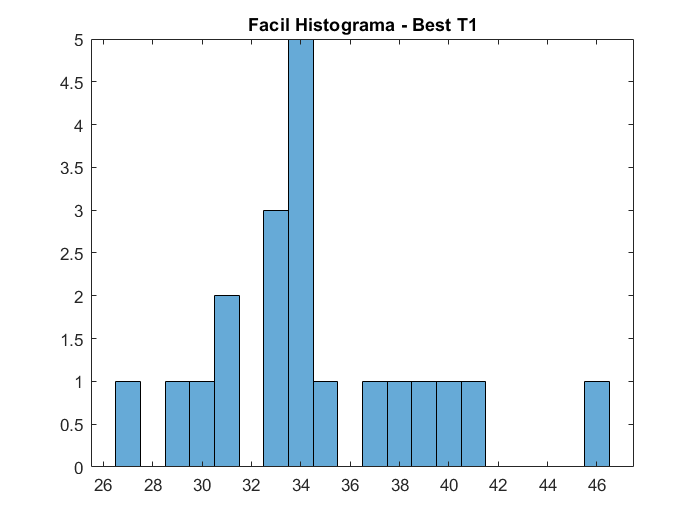


histogram(Thresh_Facil.Best_T1)
title("Facil Histograma - Best T1")

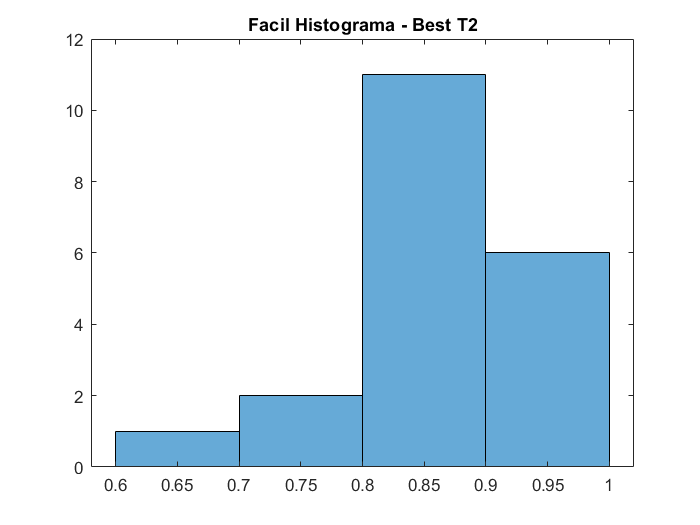


histogram(Thresh_Facil.Best_T2)
title("Facil Histograma - Best T2")

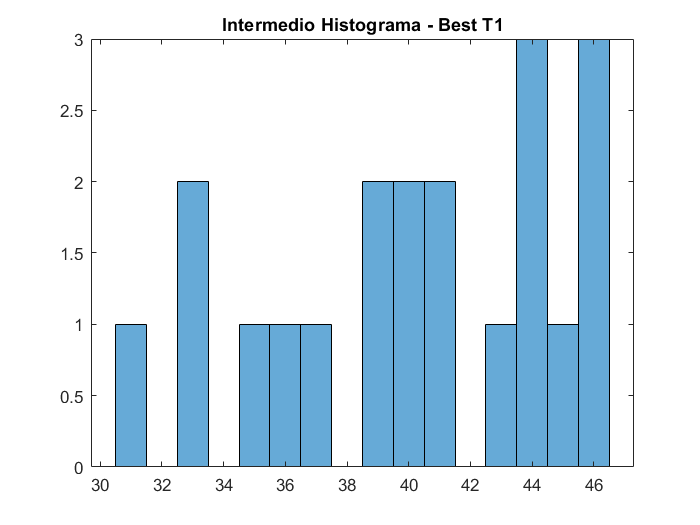


histogram(Thresh_Intermedio.Best_T1)
title("Intermedio Histograma - Best T1")

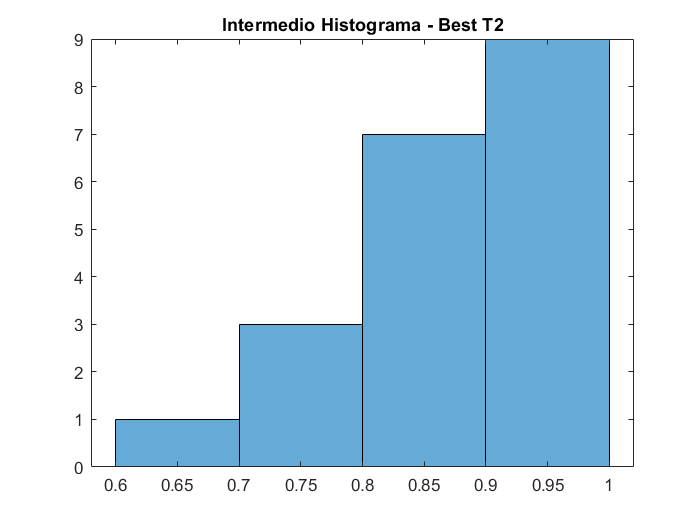


histogram(Thresh_Intermedio.Best_T2)
title("Intermedio Histograma - Best T2")